## Loading memories from images

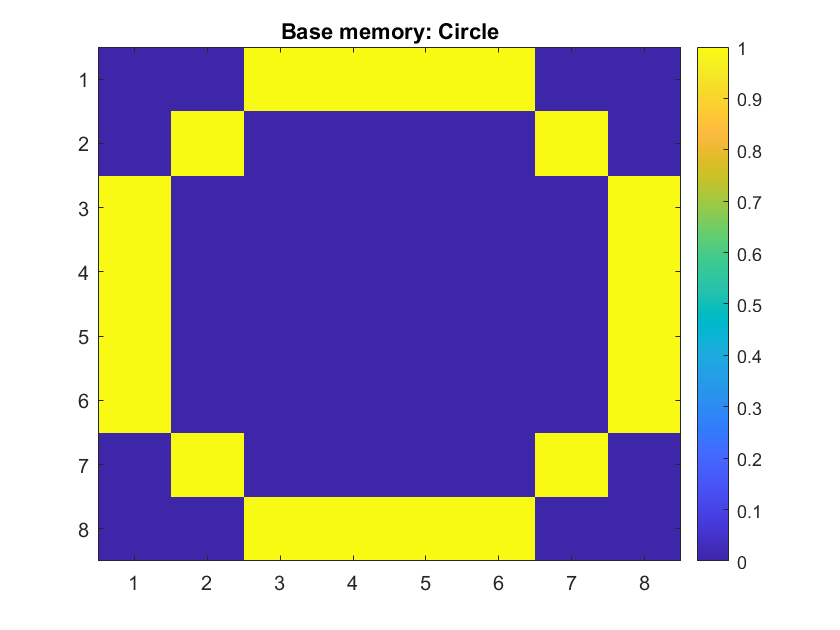

clear all;

% Import images as an matrix with values between 0 and 1
img_cir = rgb2gray(imread('Images/circle.png')) / 255;
img_squ = rgb2gray(imread('Images/square.png')) / 255;
img_tri = rgb2gray(imread('Images/triangle.png')) / 255;
img_cre = rgb2gray(imread('Images/crecent.png')) / 255;

% Print memories
image(img_cir,'CDataMapping','scaled')
title("Base memory: Circle")
colorbar

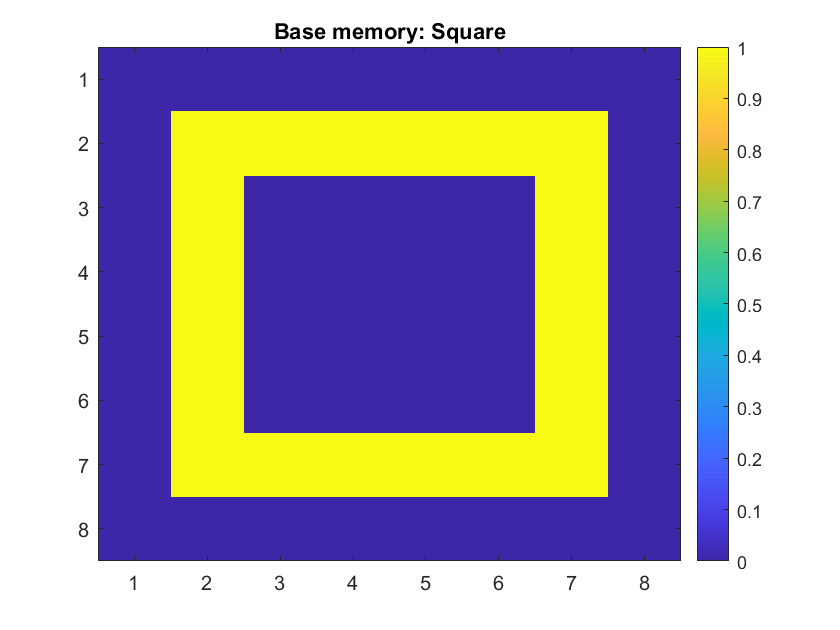

image(img_squ,'CDataMapping','scaled')
title("Base memory: Square")
colorbar

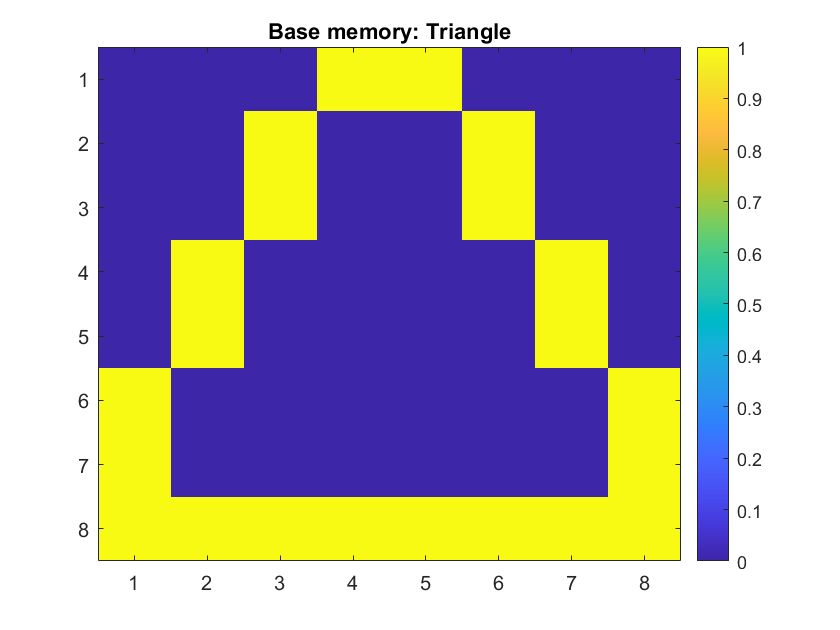

image(img_tri,'CDataMapping','scaled')
title("Base memory: Triangle")
colorbar

%image(img_cre,'CDataMapping','scaled')
%title("Base memory: Crecent")
%colorbar

% Rescale the matrices to vectors
Memories.cir = reshape(img_cir,1,[]);
Memories.squ = reshape(img_squ,1,[]);
Memories.tri = reshape(img_tri,1,[]);
%Memories.cre = reshape(img_cre,1,[]);

clear img_cre img_tri img_cir img_squ;

## Generating the weigth matrix from the memories

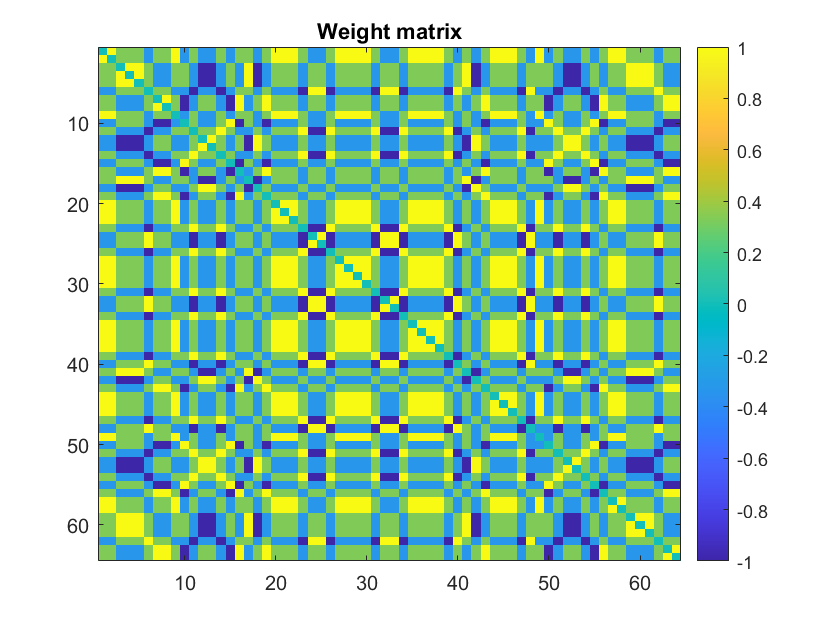

% Define weight matrix
W = zeros(64,64);

% For each memory we want to store in the network
mem_names = fieldnames(Memories);
for idx = 1:numel(mem_names)
    % Compute its inpact on the weigth values:
    mem_vec = double(Memories.(mem_names{idx}));
    W = W + 4 * (mem_vec' - 0.5) * (mem_vec - 0.5);
end

% Normalise W by the amount of memories
W = W / numel(mem_names);

% Remove self connections (diagonal)
W = W - eye(64);

image(W,'CDataMapping','scaled')
title("Weight matrix")
colorbar


clear mem_names mem_vec idx;

## Defining the user input

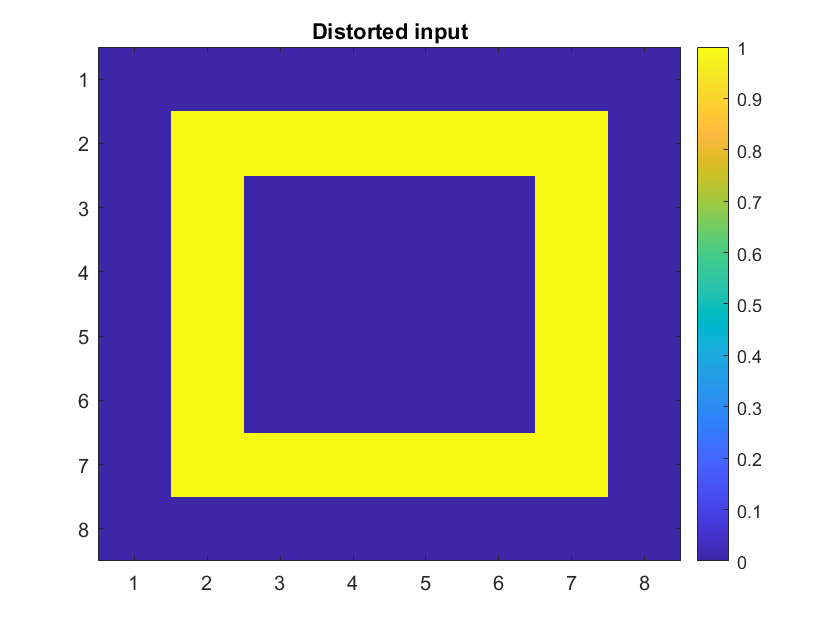

input_vec = [
    0 0 0 0 0 0 0 0
    0 1 1 1 1 1 1 0
    0 1 0 0 0 0 1 0
    0 1 0 0 0 0 1 0
    0 1 0 0 0 0 1 0
    0 1 0 0 0 0 1 0
    0 1 1 1 1 1 1 0
    0 0 0 0 0 0 0 0];
image(input_vec,'CDataMapping','scaled')
title("Distorted input")
colorbar


% Map the input values to a vector with {-1,1}
input_vec = 2 * (reshape(input_vec,[],1) - 0.5);

% find indices of excitatory/inhibitory neurons
excit_idx = find(input_vec>0);
inh_idx = find(input_vec<0);

Ne = size(excit_idx,1);          
Ni = size(inh_idx,1);

re = rand(Ne,1);
ri = rand(Ni,1);
a = [];
b = [];
c = [];
d = [];

## Define Simulation parameters

num_Neuron = 64;
sim_time=1000;                  % simulation time, ms^-1

step=0.5;
I_amplifier = 15;
W_scaling_factor = 2;

a(excit_idx) = 0.02 ;           % Time scale of recovery u(t),
a(inh_idx) = 0.02+0.08*ri;

b(excit_idx) = 0.2;             % Sensitivity of u(t) to fluctuations in v(t)
b(inh_idx)= 0.25-0.05*ri;

c(excit_idx)= -65+15*re.^2;     % After spike reset value of v(t)
c(inh_idx) = -65;

d(excit_idx)=8-6*re.^2;         % After spike reset of u(t)
d(inh_idx)=2;

a=a';b=b';c=c';d=d';

## Initialising simulation variables

rng(123)                        % seed for reproducibility 
v=-65*ones(num_Neuron,1);       % Initial values of v
u=b.*v;                         % Initial values of u
firings=[];                     % spike timings
stateV=zeros(sim_time,num_Neuron);
stateU=zeros(sim_time,num_Neuron);
dv = @(v,u,I,dt)    dt * (0.04*v.^2 + 5*v + 140 - u + I);
du = @(v,u,a,b,dt)  dt * a.*(b.*v - u);

## Run simulation

for t = 1:sim_time                       % simulation of 100 ms with a microsecond resolution
  I = 2*randn(num_Neuron, 1);           % generate noise
  I(excit_idx) = I_amplifier*I(excit_idx); % amplify signal which comes from "ON" neurons
  fired = find(v>=30);                  % indices of spikes
  firings = [firings; t+0*fired,fired]; % add fired neurons to the firings matrix
  v(fired) = c(fired);                  % reset voltage of fired neurons
  u(fired) = u(fired) + d(fired);       % reset recovery variable of fired neurons
  I = I + sum(W_scaling_factor * W(:,fired),2);            % Add input from fired neurons
  v = v + step*dv(v,u,I,1);
  u = u + du(v,u,a,b,1);
  stateV(t,:) = v(:,:);
  stateU(t,:) = u(:,:);
end

## Plotting results

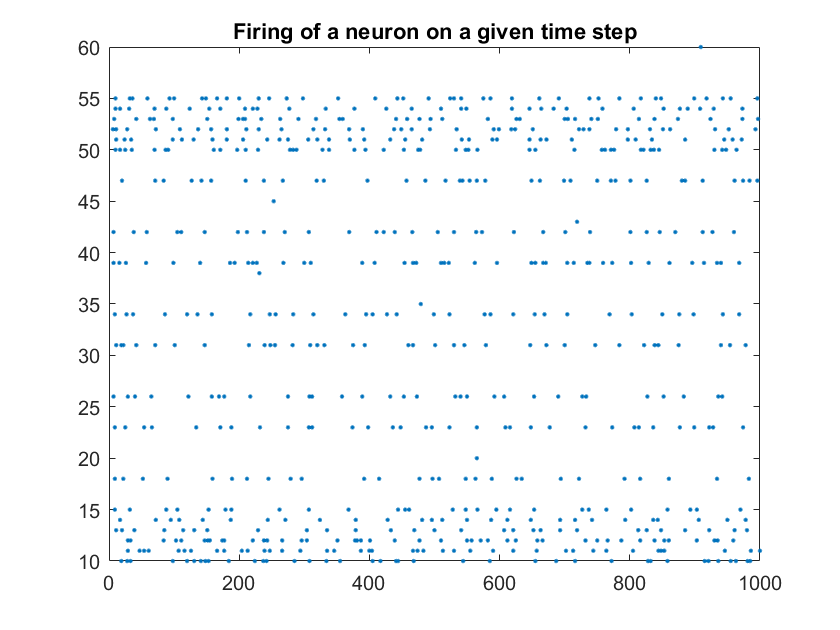

% Plot fired neurons over time
plot(firings(:,1),firings(:,2),'.');
title("Firing of a neuron on a given time step")

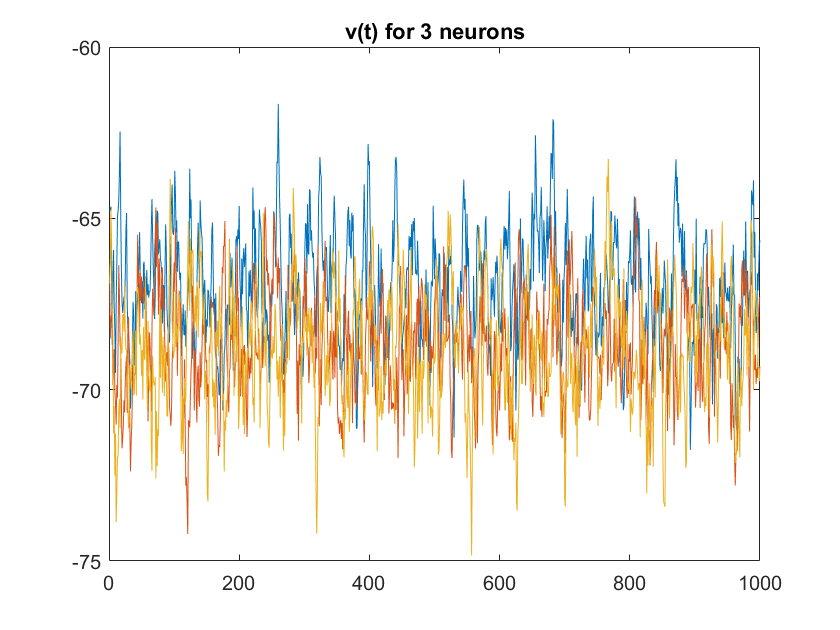


% Plotthe state over time of neuron 1
plot(1:sim_time, stateV(:,1:3))
title("v(t) for 3 neurons")

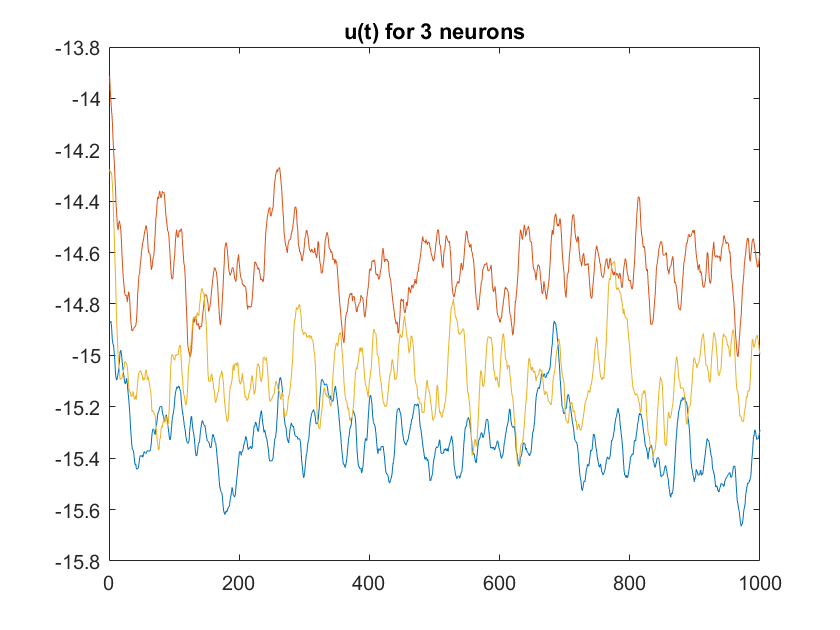

plot(1:sim_time, stateU(:,1:3))
title("u(t) for 3 neurons")

## Rendering output

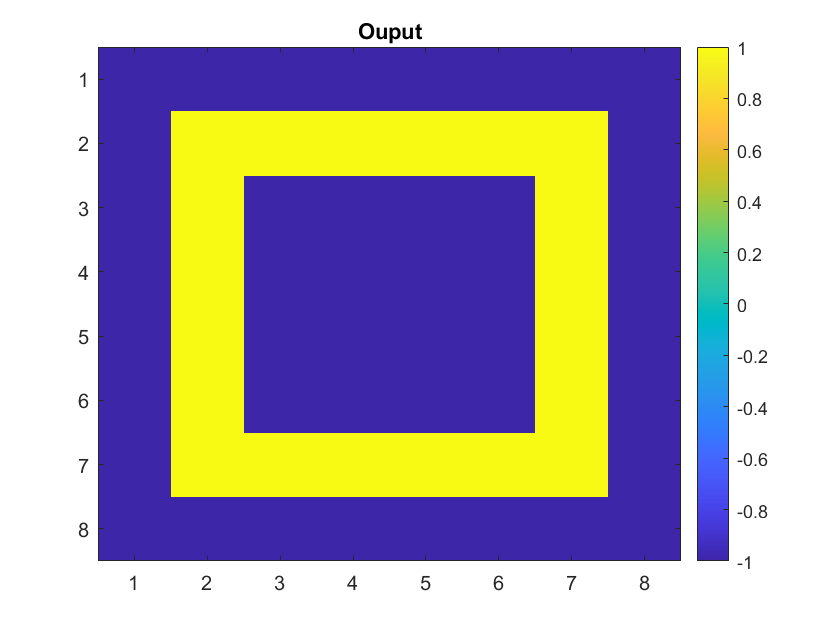

% Number of measurements to consider for the final output
cutoff =87;

% Find the index in the firings array where this cutoff happence
[minVal, closestIdx] = min(abs(firings(:,1) - 1000 + cutoff));
if (minVal ~= 0)
    closestIdx = closestIdx + 1;
end

% Process the fired neurons
output = zeros(64,1);
for idx = closestIdx:size(firings,1)
    output(firings(idx,2)) = 1;
end

output = 2 * (reshape(output,8,8) - 0.5);

image(output,'CDataMapping','scaled')
title("Ouput")
colorbar